clc;clear

load S.mat

noise_std=6.3*1e-4;
L=8;

[Ratio,Ratio_std]=CalculateRatio(S,L,noise_std);


xi_x=(0:0.1:0.2);
xi_z=0.2;
xi_y=-xi_z-xi_x;


A0=xi_z.^2/4+(xi_x+xi_y).^2/8;
A2=(xi_x-xi_y).^2/16;
Ratio_theo=A2./A0

Ratio_theo =     0.1667    0.6667    1.5000


marker={'o','^','s'};
Jbar=1.4595; %in kHz
tau_0=24*5/1e3; %in ms
loop=[10:10:60];
x=loop(1:end);

figure()
ylim_seq=[0.1,0.2;0.6,0.7;1.45,1.55];
for i=1:3
    subplot(3,1,i)
    error_bar=1.96*Ratio_std((i-1)*length(loop)+1:i*length(loop));
    y=Ratio((i-1)*length(loop)+1:i*length(loop))
    errorbar(x,y,error_bar,marker{i},'MarkerSize',4,'CapSize',3)
    hold on
    plot([0,x(end)],Ratio_theo(i)*ones(1,2),'b:')
    xlabel('Number of cycles $n$ ','Interpreter','latex')
    % xlabel('$\bar{J}t/2\pi$ ','Interpreter','latex')
    ylabel('$I_2^{(z)}/I_0^{(z)}$','Interpreter','latex')

    % xlim([0 11])
    xticks([0:10:60])
    ylim(ylim_seq(i,:))
    yticks(sort([Ratio_theo,ylim_seq(i,:)]))
    title(['{$\bf{\xi}$}$^{(0)}=(',num2str(xi_x(i)),',',num2str(xi_y(i)),',',num2str(xi_z),')$'],'interpreter','latex')
end

y =     0.1602    0.1622    0.1636    0.1629    0.1616    0.1605


y =     0.6389    0.6547    0.6547    0.6543    0.6564    0.6517


y =     1.4882    1.4866    1.4938    1.4872    1.4922    1.4854


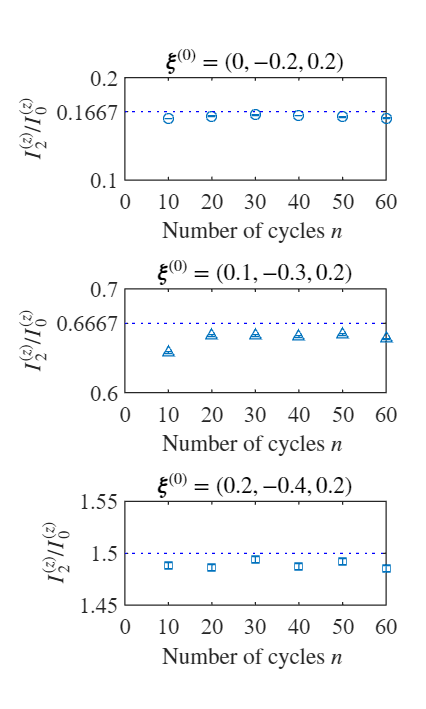

    fontsize(gcf,9,'points')
    fontname(gcf,"Times New Roman")
    set(gcf,'unit','centimeters','position',[10,10,6,10]);

function [Ratio,Ratio_std]=CalculateRatio(S,L,noise_std)

RealPart=real(fftshift(fft(S,L,2)/L,2));

ZeroOrder=RealPart(:,L/2+1);
DoubleOrder=RealPart(:,L/2+1-2);

Ratio=(DoubleOrder./ZeroOrder)';
var_Double=noise_std^2/2/L;
var_Zero=noise_std^2/L;
Ratio_std=sqrt(var_Double./(ZeroOrder.^2)+var_Zero*(DoubleOrder.^2)./(ZeroOrder.^4));  %ref: https://www.pianshen.com/article/71539931/
end
